✅ Paths added.
Equilibrium X_eta = [eta; eta_dot]:
     0     0     0     0     0     0     0     0     0     0

Equilibrium input Ueq (torques):
         0         0         0  -13.7174   -1.8085

‖f(Xeq,Ueq)‖ = 0.000e+00 (should be ~0 at equilibrium)
=== REDUCED (eta, eta_dot) LINEAR MODEL ===
Eigenvalues of A_eta:
         0         0         0   -2.3653         0   -1.2062   -0.0000   -0.2092   -0.9095  -17.3666

rank(ctrb(A_eta,B_eta)) = 10 of 10
rank(obsv(A_eta,C_eta)) = 10 of 10

Closed-loop eigenvalues (LQR):
   1.0e+02 *

  -0.3734 + 0.0000i  -0.1344 + 0.0000i  -1.1116 + 0.0000i  -0.0194 + 0.0143i  -0.0194 - 0.0143i  -0.0324 + 0.0000i  -0.0317 + 0.0000i  -0.0419 + 0.0079i  -0.0419 - 0.0079i  -0.0312 + 0.0000i



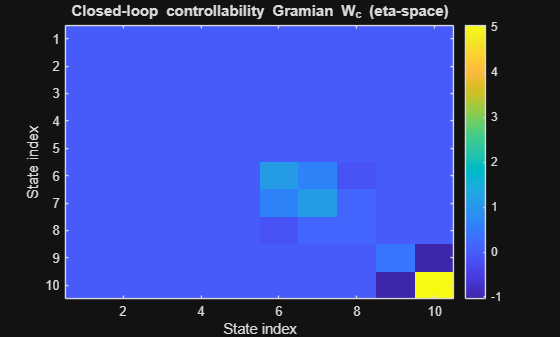

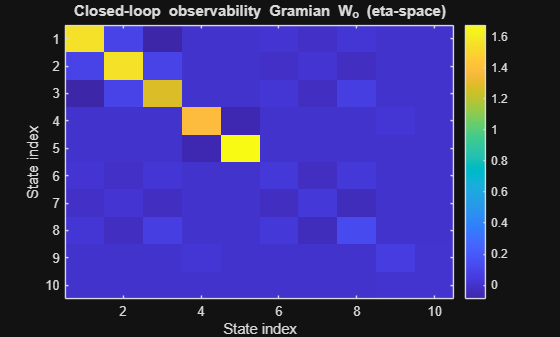


cond(Wc) = 7.059e+02
cond(Wo) = 3.849e+02


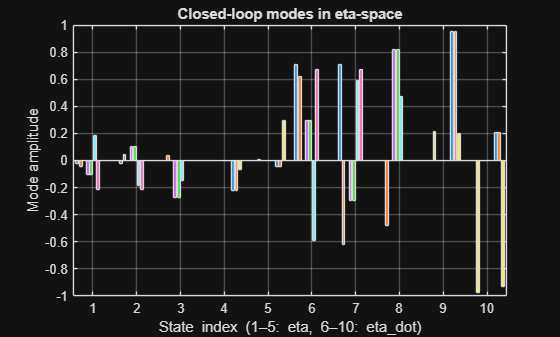

mm_linear_analysis_eta_optionA

function mm_linear_analysis_eta_optionA()
% MM_LINEAR_ANALYSIS_ETA_OPTIONA
% Linear analysis in minimal coordinates X_eta = [eta; eta_dot]
% around a chosen equilibrium (here: theta2 = -pi/2).
%
% State ordering:
%   eta     = [theta_r; theta_l; theta_1; theta_2; theta_3]  (1..5)
%   eta_dot = [same order]                                   (6..10)

    clc; clearvars; close all;

    project_root = './';
    addpath(fullfile(project_root, 'dynamics_library'));
    addpath(fullfile(project_root, 'data'));

    disp('✅ Paths added.');

    %% 1) Build equilibrium in eta-coordinates
    [Xeq_eta, Ueq] = mm_build_eta_equilibrium_optionA();
    nx = length(Xeq_eta);
    nu = length(Ueq);

    fprintf('Equilibrium X_eta = [eta; eta_dot]:\n');
    disp(Xeq_eta.');
    fprintf('Equilibrium input Ueq (torques):\n');
    disp(Ueq.');

    %% 2) Define reduced nonlinear dynamics f_eta(X_eta, tau)
    f_eta = @(Xeta, U) mm_eta_dynamics_reduced(Xeta, U);

    %% 3) Numerical linearization in minimal coordinates
    [A_eta, B_eta] = mm_numeric_linearize(f_eta, Xeq_eta, Ueq);

    C_eta = eye(nx);   % observe all states
    disp('=== REDUCED (eta, eta_dot) LINEAR MODEL ===');
    mm_analyze_linear_model_basic(A_eta, B_eta, C_eta);

    %% 4) Design stabilizing feedback on (A_eta, B_eta)
    % --- Option 1: pole placement (commented, for reference) ---
    % desired_poles = -[1 1.5 2 2.5 3 3.5 4 4.5 5 6];
    % K_eta_place = place(A_eta, B_eta, desired_poles);
    % A_cl_place  = A_eta - B_eta*K_eta_place;
    % fprintf('\nClosed-loop eigenvalues (pole placement):\n');
    % disp(eig(A_cl_place).');

    % --- Option 2: LQR (used for the rest of the analysis) ---
    Q = diag([10 10 10 10 10  1 1 1 1 1]);  % positions vs velocities
    R = 0.1*eye(nu);                        % torque penalty

    K_eta = lqr(A_eta, B_eta, Q, R);
    A_cl  = A_eta - B_eta*K_eta;

    fprintf('\nClosed-loop eigenvalues (LQR):\n');
    disp(eig(A_cl).');

    %% 5) Closed-loop Gramians in eta-space
    D_eta = zeros(nx, nu);
    sys_cl = ss(A_cl, B_eta, C_eta, D_eta);

    if all(real(eig(A_cl)) < 0)
        Wc = gram(sys_cl, 'c');
        Wo = gram(sys_cl, 'o');

        figure; imagesc(Wc); colorbar;
        title('Closed-loop controllability Gramian W_c (eta-space)');
        xlabel('State index'); ylabel('State index');

        figure; imagesc(Wo); colorbar;
        title('Closed-loop observability Gramian W_o (eta-space)');
        xlabel('State index'); ylabel('State index');

        fprintf('\ncond(Wc) = %.3e\n', cond(Wc));
        fprintf('cond(Wo) = %.3e\n', cond(Wo));
    else
        warning('A_cl is not Hurwitz – cannot compute infinite-horizon Gramians.');
    end

    %% 6) Closed-loop modes (eigenvectors) in eta-space
    [V_cl, ~] = eig(A_cl);

    figure;
    bar(real(V_cl));        % use real part for plotting
    grid on;
    title('Closed-loop modes in eta-space');
    xlabel('State index (1–5: eta, 6–10: eta\_dot)');
    ylabel('Mode amplitude');

end


%% ======= Helpers =======

function [Xeq_eta, Ueq] = mm_build_eta_equilibrium_optionA()
% Option A (non-singular): base fixed at origin,
%   theta_r = theta_l = theta_1 = theta_3 = 0,
%   theta_2 = -pi/2.
%
% eta     = [theta_r; theta_l; theta_1; theta_2; theta_3]
% eta_dot = 0 at equilibrium.
% Xeq = {
%     [zeros(6,1);  pi/4;  pi/4;  ones(2,1); zeros(3,1)];   % eq1:  θ2 = +π/2, θ3 = 0
%     [zeros(6,1);  pi/2;  0;  ones(5,1)];   % eq1:  θ2 = +π/2, θ3 = 0
%     [zeros(6,1);  pi/2;  0;  zeros(5,1)];   % eq1:  θ2 = +π/2, θ3 = 0
%     [zeros(6,1); -pi/2;  0;  zeros(5,1)];   % eq2:  θ2 = -π/2, θ3 = 0
%     [zeros(6,1);  pi/2;  pi; zeros(5,1)];   % eq3:  θ2 = +π/2, θ3 = π
%     [zeros(6,1); -pi/2;  pi; zeros(5,1)];   % eq4:  θ2 = -π/2, θ3 = π
% };
    x_b0     = 0;
    y_b0     = 0;
    theta_m0 = 0;

    eta_eq = [ ...
        0;        % theta_r
        0;        % theta_l
        0;        % theta_1
        0;     % theta_2
        0];       % theta_3

    eta_dot_eq = zeros(5,1);

    % Full q needed to compute G1, B1
    q_eq = [x_b0; y_b0; theta_m0; eta_eq];

    % At equilibrium: M1*0 + (C1+D)*0 + G1 = B1 * tau_eq
    M1 = mm_M1_fun(q_eq); %#ok<NASGU>
    B1 = mm_B1_fun(q_eq);
    G1 = mm_G1_fun(q_eq);

    tau_eq = B1 \ G1;

    Xeq_eta = [eta_eq; eta_dot_eq];
    Ueq     = tau_eq;
end


function dXeta = mm_eta_dynamics_reduced(Xeta, tau)
% Minimal-order dynamics in eta-coordinates:
%   X_eta = [eta; eta_dot],  dim = 10

    ne = 5;
    eta     = Xeta(1:ne);
    eta_dot = Xeta(ne+1:end);

    % Base pose fixed at equilibrium
    x_b0     = 0;
    y_b0     = 0;
    theta_m0 = 0;

    q = [x_b0; y_b0; theta_m0; eta];

    % Kinematics for q_dot
    R_q   = mm_R_fun(q);     % 8x5
    q_dot = R_q * eta_dot;   % 8x1

    % Reduced dynamics matrices
    M1 = mm_M1_fun(q);       % 5x5
    C1 = mm_C1_fun(q, q_dot);
    G1 = mm_G1_fun(q);
    B1 = mm_B1_fun(q);

    % Damping
    persistent D_eta
    if isempty(D_eta)
        data  = load('./data/mm_dynamics_reduced.mat','D_eta');
        D_eta = data.D_eta;
    end

    % M1*eta_ddot + (C1 + D_eta)*eta_dot + G1 = B1*tau
    eta_ddot = M1 \ (B1*tau - (C1 + D_eta)*eta_dot - G1);

    dXeta = [eta_dot; eta_ddot];
end


function [A,B] = mm_numeric_linearize(f, Xeq, Ueq)
% Numeric linearization: xdot = f(x,u)

    nx = length(Xeq);
    nu = length(Ueq);

    A = zeros(nx,nx);
    B = zeros(nx,nu);

    eps = 1e-6;

    f0 = f(Xeq, Ueq);
    fprintf('‖f(Xeq,Ueq)‖ = %.3e (should be ~0 at equilibrium)\n', norm(f0));

    for i = 1:nx
        Xp = Xeq; Xp(i) = Xp(i) + eps;
        Xm = Xeq; Xm(i) = Xm(i) - eps;

        fp = f(Xp, Ueq);
        fm = f(Xm, Ueq);

        A(:,i) = (fp - fm) / (2*eps);
    end

    for j = 1:nu
        Up = Ueq; Up(j) = Up(j) + eps;
        Um = Ueq; Um(j) = Um(j) - eps;

        fp = f(Xeq, Up);
        fm = f(Xeq, Um);

        B(:,j) = (fp - fm) / (2*eps);
    end
end


function mm_analyze_linear_model_basic(A,B,C)
% Basic eigenvalues + controllability / observability ranks

    lambda = eig(A);
    disp('Eigenvalues of A_eta:');
    disp(lambda.');

    Co = ctrb(A,B);
    Ob = obsv(A,C);

    fprintf('rank(ctrb(A_eta,B_eta)) = %d of %d\n', rank(Co), size(A,1));
    fprintf('rank(obsv(A_eta,C_eta)) = %d of %d\n', rank(Ob), size(A,1));
end

